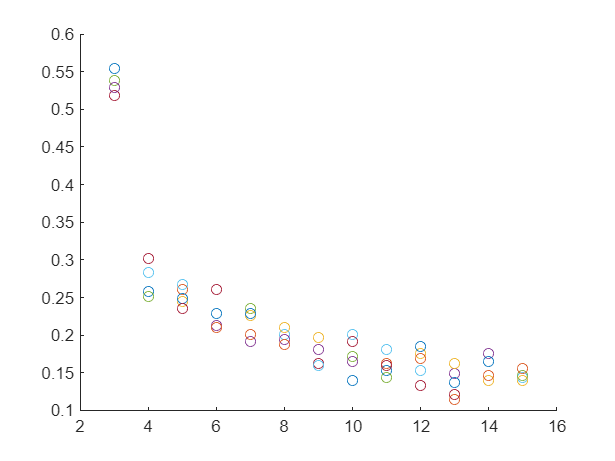

Results = "Complete"

Number_of_Qubits = 1;
Number_of_walks = 5;
Precision = pi/2 - acos(1/sqrt(2^Number_of_Qubits));

Results = Plotting_Function(Number_of_walks, Number_of_Qubits, Precision)

function Plot = Plotting_Function(Number_of_walks, Number_of_Qubits, Precision)

Step_Size_Data = [];
Critical_Step_size = [];
Number_of_steps_data =[];

Number_of_steps_data_EXPORT = zeros(13, Number_of_walks);
Step_Size_Data_EXPORT = zeros(13, Number_of_walks);

    for j = 1:Number_of_walks
        for Number_of_steps = 3:15
            
            Critical_Step_size = [];
                Number_of_steps_data =[];
    
            for Step_Size = 0:0.005:(pi*0.5)
                for i = 1:Number_of_walks
                
                Walk = Random_Walk(Number_of_Qubits, Number_of_steps, Step_Size, Precision);
    
                    if Walk ~= 0
                        Step_Size_Data = [Step_Size_Data Step_Size];
                    break
                    end
                end 
    
                 if isempty(Step_Size_Data) == 0
                 
                    hold on
        
                    Critical_Step_size = [Critical_Step_size mean(Step_Size_Data)];
                    Number_of_steps_data =[Number_of_steps_data Number_of_steps];

                    scatter(Number_of_steps, (2/pi)*(mean(Step_Size_Data)));
                    Step_Size_Data = [];
                
                    hold off
    
                break
                 end
            end
        end 
    end

    Plot = "Complete";
end

function State = State_Generator(Parameters, Dimensions)
    
    State = zeros(Dimensions,1);
    Array_of_Sines = ones(Dimensions-1,1);
    
    for i = 1:(Dimensions-1)

        State(i,1) = exp(1i*Parameters((Dimensions-1)+ i))*prod(Array_of_Sines)*cos(Parameters(i));
        Array_of_Sines(i,1) = sin(Parameters(i));

    end

    State(Dimensions,1) = prod(Array_of_Sines);
end

function Derivative_States = Partial_Differentiator(Parameters, Dimensions)

    Derivative_States = zeros(Dimensions,2*(Dimensions-1));
    Derivative_State = zeros(Dimensions,1);

    for i = 1:(Dimensions-1)

        Array_of_Sines = ones(Dimensions-1,1);
        Array_of_Sines(1:i,1) = sin(Parameters(1:i));

        Derivative_State(i,1) = (-1)*exp(1i*Parameters(i+(Dimensions-1)))*prod(Array_of_Sines);
        Array_of_Sines(i,1) = 1;

        for j = i+1:(Dimensions-1)
    
            Derivative_State(j,1) = exp(1i*Parameters(j+(Dimensions-1)))*prod(Array_of_Sines)*cos(Parameters(i))*cos(Parameters(j));
            Array_of_Sines(j) = sin(Parameters(j));
        end

       Derivative_State(Dimensions) = prod(Array_of_Sines)*cos(Parameters(i));
   
       Derivative_States(:,i) = Derivative_State;

    end


    for i = Dimensions:2*(Dimensions-1)

    Array_of_Sines(i-(Dimensions-1):Dimensions) = 1;

    Derivative_States(i-(Dimensions-1),i) = 1i*exp(1i*Parameters(i))*prod(Array_of_Sines)*cos(Parameters(i-(Dimensions-1)));
    
    Array_of_Sines(i-(Dimensions-1)) = sin(Parameters(i-(Dimensions-1)));

    end
end

function RWV = Random_Walk_Vector(Dimensions)
    
    Local_Vector = randn(2*(Dimensions-1),1);
    Summated_Vector = sum(Local_Vector.^2);

    RWV = Local_Vector./sqrt(Summated_Vector);

end 

function MGF = Metric_Generating_Function(Dimensions, Original_State, Initial_Parameters)

    FS_Matrix = zeros(Dimensions,Dimensions);
    Partial_Derivative_Matrix = Partial_Differentiator(Initial_Parameters, Dimensions);

    for i = 1:2*(Dimensions-1) 
        for j = 1:2*(Dimensions-1)
            
            FS_Matrix(i,j) = dot(Partial_Derivative_Matrix(:,i), Partial_Derivative_Matrix(:,j)) - (dot(Partial_Derivative_Matrix(:,i), Original_State))*(dot(Original_State, Partial_Derivative_Matrix(:,j)));
        end
    end

    MGF = (FS_Matrix + FS_Matrix')*0.5;
end

function Step = Step_Generator(Step_Size, Dimensions, Initial_Parameters, First_State)

    Array_Dimensions = 2*(Dimensions - 1);
    pre_Theta = zeros(Array_Dimensions:1,1);
 
    u = Random_Walk_Vector(Dimensions);
    g = Metric_Generating_Function(Dimensions, First_State, Initial_Parameters);
    [V,H] = eig(g);
    h = diag(H);

     pre_Theta(1:Array_Dimensions,1) = (Step_Size/sqrt(h(1:Array_Dimensions,1)))*u(1:Array_Dimensions,1);
  

  Step = V*pre_Theta;

end

function R = Random_Walk(Number_of_Qubits, Number_of_Steps, Step_size, Precision)

    Dimension_of_Hilbert_Space = 2^(Number_of_Qubits);
    Final_Distances = [];
    Distances = zeros(Number_of_Steps,1);

        State_Parameters(:,1)= zeros(2*(Dimension_of_Hilbert_Space -1),1);
        State_Vectors(:,1) = State_Generator(State_Parameters(:,1), Dimension_of_Hilbert_Space);
        
        for t = 2:Number_of_Steps

            State_Parameters(:,t) =  State_Parameters(:,t-1) + Step_Generator(Step_size, Dimension_of_Hilbert_Space, State_Parameters(:,t-1), State_Vectors(:,t-1));
           
            State_Vectors(:,t) = State_Generator(State_Parameters(:,t), Dimension_of_Hilbert_Space);
        end 

        Final_Distance = acos(abs(dot(State_Vectors(:,Number_of_Steps),State_Vectors(:,1))));

          if abs(pi/2 - Final_Distance) <= Precision

             R = 1;

          else
              R = 0;
   
          end
end